# Testing del metodo di Jacobi

## Esempi di utilizzo della function Jacobi

Si testa il software su matrici sparse di notevoli dimensioni, generate usando funzioni Matlab non singolari e ben condizionate. Si illustra, attraverso grafico, la struttura delle matrici di test. *Nel paragrafo Test di accuratezza sono effettuati test sulla precisione della function Jacobi*.

Un primo esempio di matrice ben condizionata; si utilizzano i parametri di default della function Jacobi:

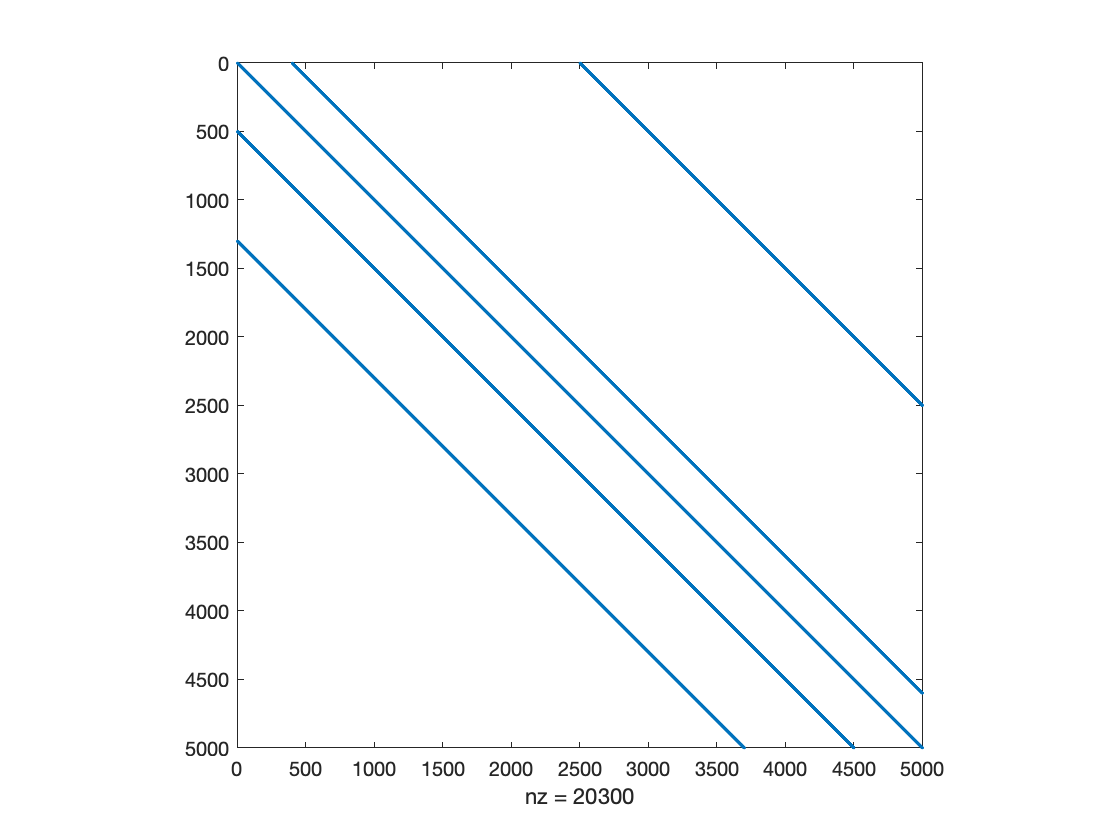

n = 5000;
e = ones(n,1);
Z = spdiags([e 3*e 15*e -e e], [-1300 -500 0 400 2500], n, n);
spy(Z)

b = Z*e;
c = condest(Z)

c =      2.269252419481776e+00


[sol, niter] = Jacobi(Z, b)

sol =      1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00


niter =     11


Esempio d'uso nel caso in cui l'utente specifichi il valore di tolleranza:

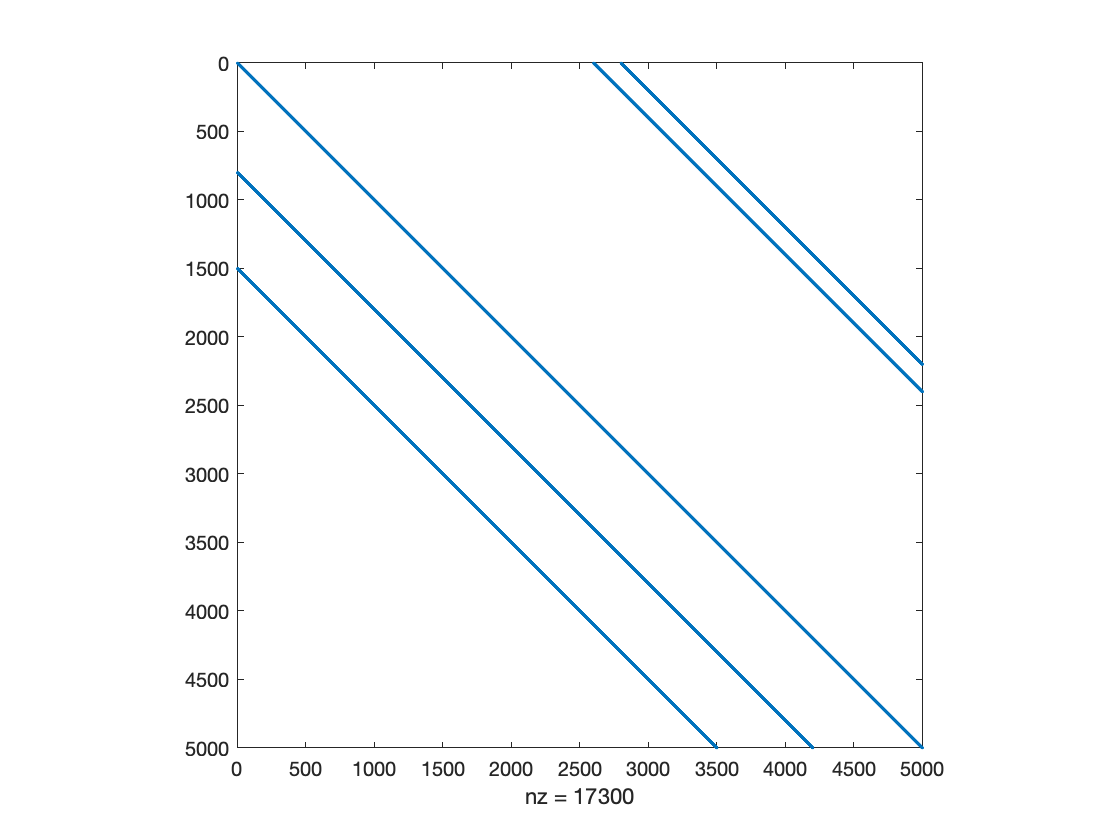

n = 5000;
e = ones(n,1);
Z = spdiags([e 6*e 10*e -e e], [-1500 -800 0 2600 2800], n, n);
spy(Z)

b = Z*e;
c = condest(Z)

c =      6.354672955765174e+00


[sol, niter] = Jacobi(Z, b, 10^-9)

sol =      1.000000000024874e+00
     1.000000000024874e+00
     1.000000000024874e+00
     1.000000000024874e+00
     1.000000000024874e+00
     1.000000000024874e+00
     1.000000000024874e+00
     1.000000000024874e+00
     1.000000000024874e+00
     1.000000000024874e+00


niter =     42


Esempio d'uso nel caso in cui l'utente specifichi il valore di tolleranza e il numero massimo di iterazioni:

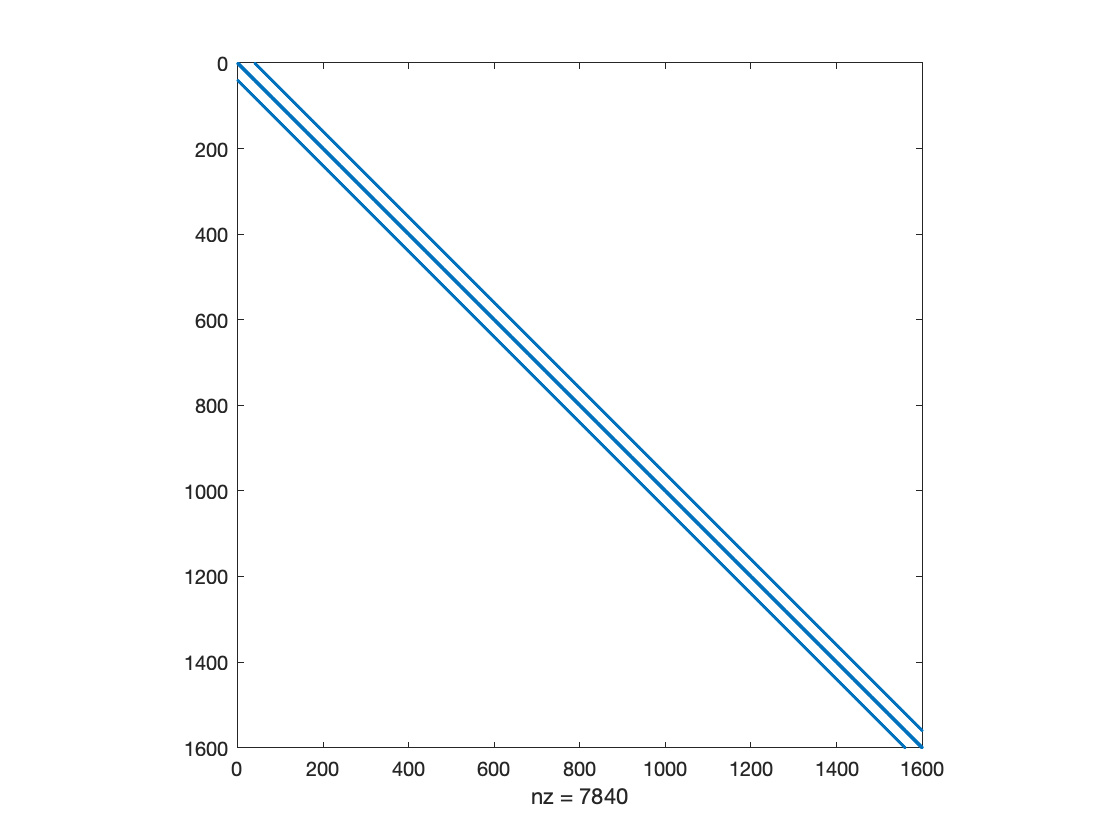

X = gallery('poisson',40);
spy(X)

c = condest(X)

c =      9.892689755980468e+02


x = ones(1600,1);
b = X*x;
[sol, niter] = Jacobi(X,b,10^-6,3000)

sol =      9.999980078246928e-01
     9.999960273402626e-01
     9.999940701689792e-01
     9.999921477963023e-01
     9.999902715034789e-01
     9.999884523013416e-01
     9.999867008656915e-01
     9.999850274746498e-01
     9.999834419483404e-01
     9.999819535912623e-01


niter =         2881


## Casi di errore

Utilizziamo la matrice sparsa di Toeppen che presenta elementi nulli sulla diagonale. Per questo tipo di matrici, il metodo di Jacobi non è definito, quindi è mostrato un messaggio di errore che invita a riordinare la matrice.

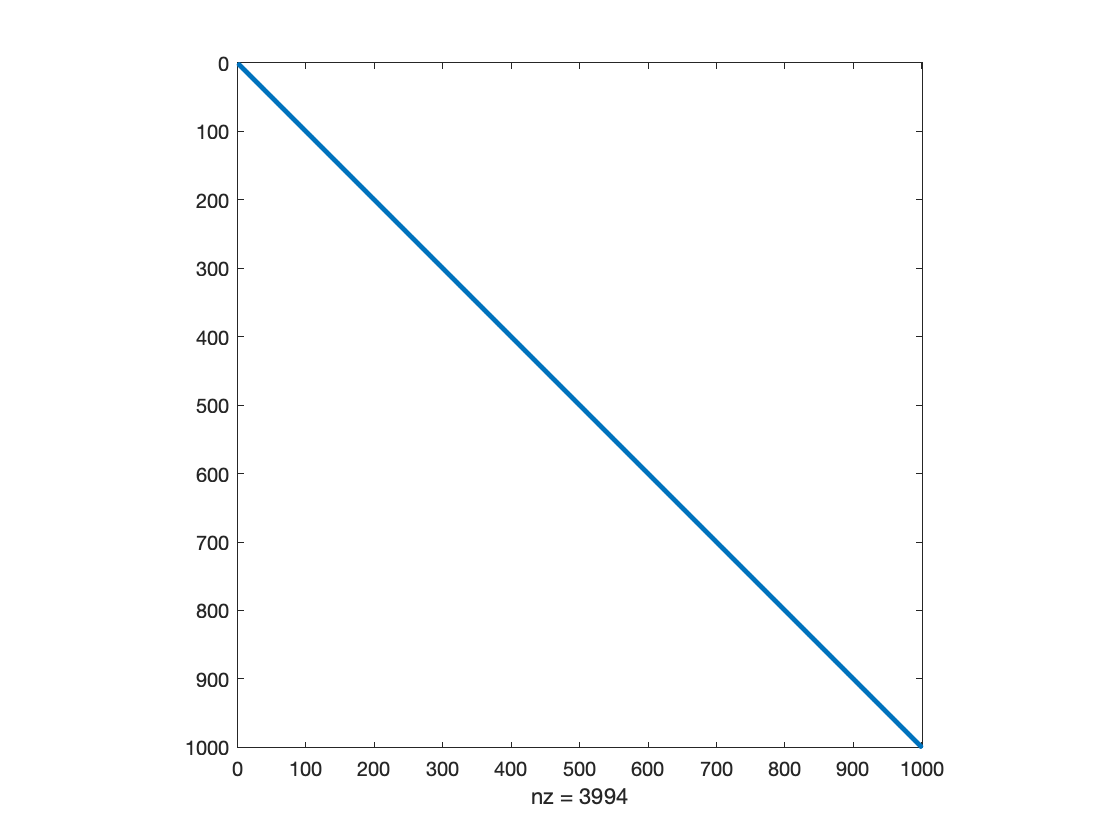

T = gallery('toeppen',1000);
spy(T)

b = T*ones(1000,1);
[sol, niter] = Jacobi(T,b)

Error using Jacobi (line 23)
La matrice A ha elementi nulli sulla diagonale. Riordinare la matrice e rieseguire l'algoritmo.

Caso in cui la matrice in ingresso è vuota.

A = [];
A = sparse(A);
[sol, niter] = Jacobi(A,b);

Error using Jacobi (line 7)
Matrice A o vettore b vuoti.

Caso in cui il vettore b in ingresso è vuoto.

A = spdiags([e 3*e 15*e -e e], [-1300 -500 0 400 2500], 50, 50);
b = [];
[sol, niter] = Jacobi(A,b);

Error using Jacobi (line 7)
Matrice A o vettore b vuoti.

Caso in cui la matrice A non è di tipo sparse.

A = [0 0 3; 1 0 0; 0 0 8];
b = rand(3,1);
[sol, niter] = Jacobi(A,b);

Error using Jacobi (line 12)
La matrice A non è tipo sparse.

Caso in cui A non è una matrice quadrata.

A = sparse(10, 12);
b = rand(10,1);
[sol, niter] = Jacobi(A,b);

Error using Jacobi (line 19)
Matrice A non quadrata.

Caso in cui b non è un vettore ma un carattere.

A = spdiags([e 3*e 15*e -e e], [-1300 -500 0 400 2500], 50, 50);
b = 'c';
[sol, niter] = Jacobi(A,b);

Error using Jacobi (line 28)
b non è un vettore.

Caso in cui b non è un vettore ma una table.

A = spdiags([e 3*e 15*e -e e], [-1300 -500 0 400 2500], 50, 50);
b = table(54,75);
[sol, niter] = Jacobi(A,b);

Error using Jacobi (line 28)
b non è un vettore.

Caso in cui b non è un vettore ma una struct.

A = spdiags([e 3*e 15*e -e e], [-1300 -500 0 400 2500], 50, 50);
b.Field = 7;
[sol, niter] = Jacobi(A,b);

Error using Jacobi (line 28)
b non è un vettore.

Caso in cui b non è un vettore numerico.

A = spdiags([e 3*e 15*e -e e], [-1300 -500 0 400 2500], 3, 3);
b = ['c','d','e'];
[sol, niter] = Jacobi(A,b);

Error using Jacobi (line 33)
Il vettore b non è vettore numerico.

Caso in cui b non rispetta le dimensioni di A.

A = spdiags([e 3*e 15*e -e e], [-1300 -500 0 400 2500], 50, 50);
b = rand(40,1);
[sol, niter] = Jacobi(A,b);

Error using Jacobi (line 40)
Il vettore dei termini noti non rispetta le dimensioni di A.

## Test di accuratezza

In questo paragrafo si confrontano i risultati ottenuti mediante la funzione di Jacobi e le soluzioni imposte. Nel primo esempio, si lavora su una matrice di dimensioni 5000x5000 e si utilizza la tolleranza di default.

### Esempio 1

n = 5000;
e = ones(n,1);
Z = spdiags([e 3*e 15*e -e e], [-1300 -500 0 400 2500], n, n);
spy(Z);

b = Z*e;
c = condest(Z)

c =      2.269252419481776e+00


B = (-1./diag(Z)')'.*(Z-diag(diag(Z)));
raggio_spettrale = max(abs(eigs(B))) % Raggio spettrale

raggio_spettrale =      3.306146307515888e-01


[sol, niter, res] = Jacobi(Z, b)

sol =      1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00


niter =     11


res =      6.623950529603319e-08


err = norm(e-sol)/norm(sol)

err =      2.969125980155711e-08


#### Errore relativo rispetto alla soluzione calcolata con bicg.

xc = bicg(Z,b)

bicg converged at iteration 10 to a solution with relative residual 7.3e-07.


xc =      9.999998291767953e-01
     9.999998291767953e-01
     9.999998291767953e-01
     9.999998291767953e-01
     9.999998291767953e-01
     9.999998291767953e-01
     9.999998291767953e-01
     9.999998291767953e-01
     9.999998291767953e-01
     9.999998291767953e-01


err_bicg = norm(xc-sol)/norm(xc)

err_bicg =      9.109366522212262e-07


Si nota che nel caso considerato la funzione *bigc* impiega meno iterazioni per ottenere il risultato con il numero di cifre significative desiderate.

### Esempio 2

Utilizzando la stessa matrice dell'esempio precedente, aumentiamo il numero di cifre significative richieste:

[sol, niter, res] = Jacobi(Z, b, 10^-13)

sol =      9.999999999999959e-01
     9.999999999999959e-01
     9.999999999999959e-01
     9.999999999999959e-01
     9.999999999999959e-01
     9.999999999999959e-01
     9.999999999999959e-01
     9.999999999999959e-01
     9.999999999999959e-01
     9.999999999999959e-01


niter =     24


res =      1.234100541057016e-14


err = norm(e-sol)/norm(sol)

err =      9.608773431926683e-15


Si osserva che gli errori relativi ottenuti sono in linea con quanto ci si aspetta.

#### Errore relativo rispetto alla soluzione calcolata con bicg.

xc = bicg(Z,b,10^-13)

bicg stopped at iteration 20 without converging to the desired tolerance 1e-13
because the maximum number of iterations was reached.
The iterate returned (number 20) has relative residual 1.5e-13.


xc =      9.999999999998932e-01
     9.999999999998932e-01
     9.999999999998932e-01
     9.999999999998932e-01
     9.999999999998932e-01
     9.999999999998932e-01
     9.999999999998932e-01
     9.999999999998932e-01
     9.999999999998932e-01
     9.999999999998932e-01


err_bicg = norm(xc-sol)/norm(xc)

err_bicg =      1.871788317512861e-13


## Velocità di convergenza

In questo paragrafo si osserva come incida il valore del raggio spettrale sul numero di iterazioni richiesto per soddisfare le specifiche dell'utente. Di seguito sono mostrati alcuni esempi.

#### Esempio 1

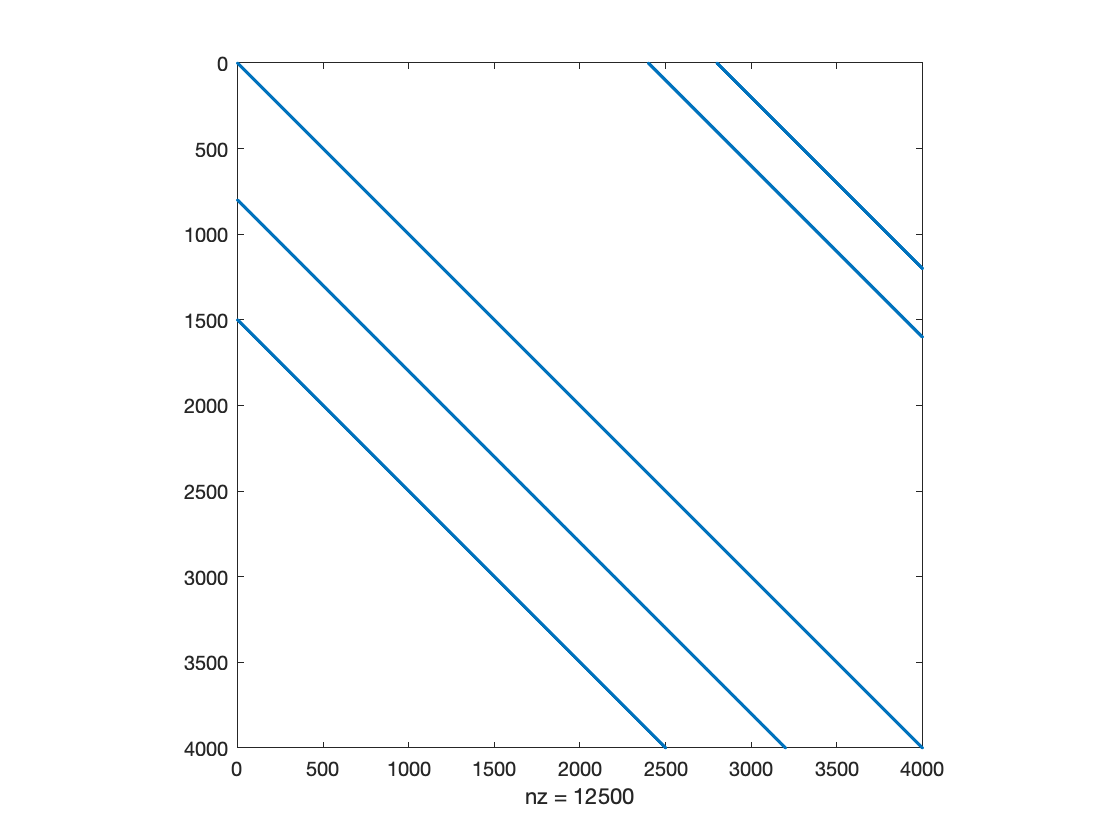

e = ones(4000,1);
Z = spdiags([e 6*e 10*e -e e], [-1500 -800 0 2400 2800], 4000, 4000);
spy(Z)

b = Z*e;
c = condest(Z)

c =      4.865382287085718e+00


[sol, niter] = Jacobi(Z, b, 10^-7)

sol =      1.000000004034755e+00
     1.000000004034755e+00
     1.000000004034755e+00
     1.000000004034755e+00
     1.000000004034755e+00
     1.000000004034755e+00
     1.000000004034755e+00
     1.000000004034755e+00
     1.000000004034755e+00
     1.000000004034755e+00


niter =     27


B = (-1./diag(Z)')'.*(Z-diag(diag(Z)));
raggio_spettrale = max(abs(eigs(B))) % Raggio spettrale

raggio_spettrale =      5.644619182878536e-01


#### Esempio 2

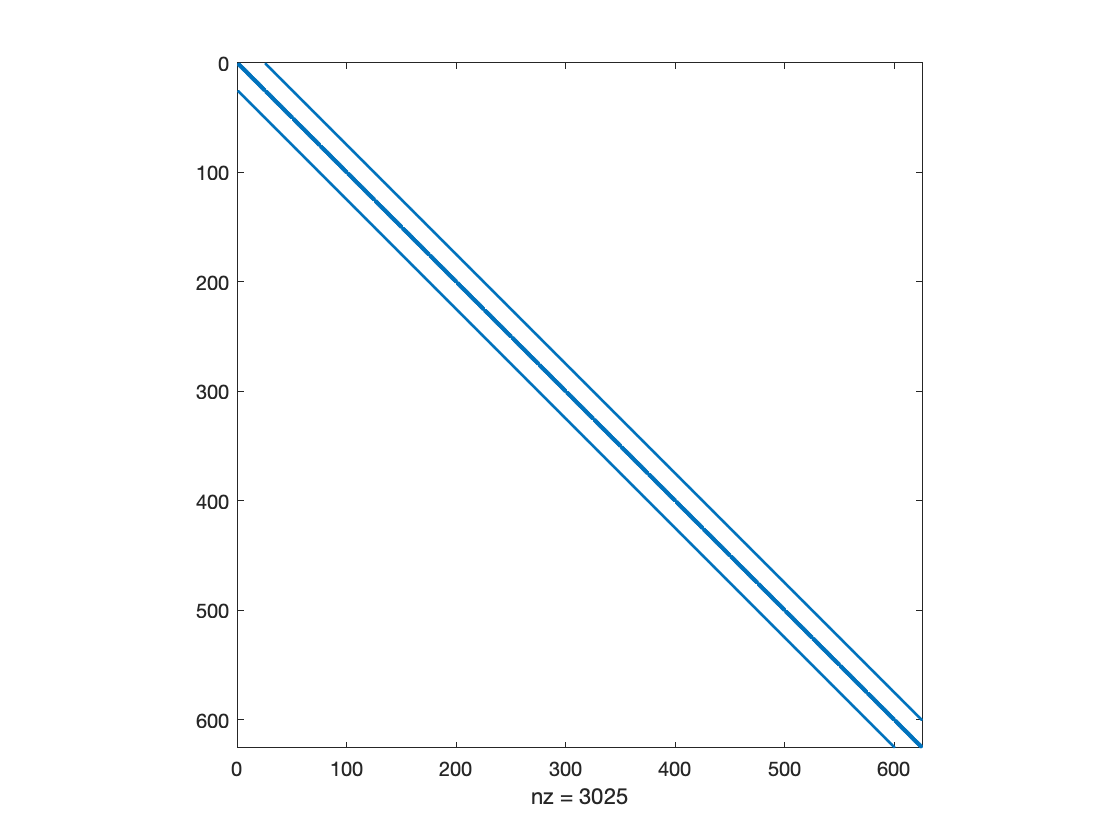

A = gallery('poisson',25);
spy(A);

c = condest(A)

c =      3.979511906492402e+02


x = ones(625,1);
b = A*x;
[sol, niter] = Jacobi(A, b, 10^-7,1800)

sol =      9.999998039306583e-01
     9.999996107308720e-01
     9.999994231868126e-01
     9.999992440846508e-01
     9.999990759652524e-01
     9.999989213694822e-01
     9.999987824452332e-01
     9.999986613403985e-01
     9.999985596850713e-01
     9.999984791093450e-01


niter =         1597


B = (-1./diag(A)')'.*(A-diag(diag(A)));
raggio_spettrale = max(abs(eigs(B))) % Raggio spettrale

raggio_spettrale =      9.927088740980556e-01


Nell'esempio 1, l'algoritmo converge in 27 iterazioni con precisione a 7 cifre. La seconda esecuzione, a parità di cifre significative richieste, converge in 1597 iterazioni. Ciò trova una spiegazione teorica nell'aumento del raggio spettrale della matrice B calcolata dal metodo di Jacobi.

## Casi di warning

Caso in cui il parametro TOL è un carattere.

A = spdiags([e 3*e 15*e -e e], [-1300 -500 0 400 2500], 50, 50);
b = rand(50,1);
[sol, niter] = Jacobi(A,b,'c');

Caso in cui il parametro TOL è minore di eps.

A = spdiags([e 3*e 15*e -e e], [-1300 -500 0 400 2500], 50, 50);
b = rand(50,1);
[sol, niter] = Jacobi(A,b,eps/2);

Caso in cui il parametro TOL non è finito.

A = spdiags([e 3*e 15*e -e e], [-1300 -500 0 400 2500], 50, 50);
b = rand(50,1);
[sol, niter] = Jacobi(A,b,inf);

Caso in cui è specificato anche il quarto parametro ma TOL non è reale.

A = spdiags([e 3*e 15*e -e e], [-1300 -500 0 400 2500], 50, 50);
b = rand(50,1);
[sol, niter] = Jacobi(A,b,5i,600);

Caso in cui il parametro MAXITER non è finito.

A = spdiags([e 3*e 15*e -e e], [-1300 -500 0 400 2500], 50, 50);
b = rand(50,1);
[sol, niter] = Jacobi(A,b,10^-9,inf);

Caso in cui il parametro MAXITER non è uno scalare.

A = spdiags([e 3*e 15*e -e e], [-1300 -500 0 400 2500], 50, 50);
b = rand(50,1);
[sol, niter] = Jacobi(A,b,10^-9,[1 2 3]);

Caso in cui il parametro MAXITER non è reale.

A = spdiags([e 3*e 15*e -e e], [-1300 -500 0 400 2500], 50, 50);
b = rand(50,1);
[sol, niter] = Jacobi(A,b,10^-9,3i);

### Warning sul numero di iterazioni massimo

Potrebbe capitare che il numero di iterazioni massimo inserito come input non sia sufficiente per ottenere il numero di cifre significative desiderato. Mostriamo di seguito alcuni esempi:

#### Esempio 1

e = ones(4000,1);
Z = spdiags([e 6*e 10*e -e e], [-1500 -800 0 2400 2800], 4000, 4000);
c = condest(Z)

c =      4.860942611353977e+00


B = (-1./diag(D)')'.*(D-diag(diag(D)));
raggio_spettrale = max(abs(eigs(B))) % Raggio spettrale

raggio_spettrale =      9.999969672077751e-01


x = ones(4000,1);
b = Z*x;
[sol, niter] = Jacobi(Z,b,10^-7,10)

sol =      1.000062937530000e+00
     1.000062937530000e+00
     1.000062937530000e+00
     1.000062937530000e+00
     1.000062937530000e+00
     1.000062937530000e+00
     1.000062937530000e+00
     1.000062937530000e+00
     1.000062937530000e+00
     1.000062937530000e+00


niter =     10


err = norm(x-sol)/norm(sol)

err =      3.218170622714500e-04


[sol, niter] = Jacobi(Z,b,10^-7,20)

sol =      9.999994742542844e-01
     9.999994742542844e-01
     9.999994742542844e-01
     9.999994742542844e-01
     9.999994742542844e-01
     9.999994742542844e-01
     9.999994742542844e-01
     9.999994742542844e-01
     9.999994742542844e-01
     9.999994742542844e-01


niter =     20


err = norm(x-sol)/norm(sol)

err =      9.682058058759779e-07


[sol, niter] = Jacobi(Z,b,10^-7,30)

sol =      1.000000004034755e+00
     1.000000004034755e+00
     1.000000004034755e+00
     1.000000004034755e+00
     1.000000004034755e+00
     1.000000004034755e+00
     1.000000004034755e+00
     1.000000004034755e+00
     1.000000004034755e+00
     1.000000004034755e+00


niter =     27


err = norm(x-sol)/norm(sol)

err =      1.699970495678674e-08


In questo caso, dato che il primo numero massimo di iterazioni è stato impostato a 10 e il secondo a 20, la function stampa un messaggio di warning specificando che il risultato potrebbe non soddisfare l'accuratezza richiesta. Nell'ultimo caso, aumentando tale parametro a 30, la function converge al risultato con accuratezza desiderata.

#### Esempio 2

X = gallery('poisson',45);
c = condest(X)

c =      1.246644559470457e+03


x = ones(2025,1);
b = X*x;
[sol, niter] = Jacobi(X,b,10^-6,1000)

sol =      9.992704954445497e-01
     9.985443905025414e-01
     9.978250847020679e-01
     9.971159140342090e-01
     9.964202142497190e-01
     9.957411952434478e-01
     9.950820665594760e-01
     9.944458519749194e-01
     9.938355748715626e-01
     9.932540164953604e-01


niter =         1000


err = norm(x-sol)/norm(sol)

err =      8.563326975071257e-02


[sol, niter] = Jacobi(X,b,10^-6,4000)

sol =      9.999980070151633e-01
     9.999960233333731e-01
     9.999940581710265e-01
     9.999921207445213e-01
     9.999902200119213e-01
     9.999883649312908e-01
     9.999865640354895e-01
     9.999848258573762e-01
     9.999831583456547e-01
     9.999815694490282e-01


niter =         3529


err = norm(x-sol)/norm(sol)

err =      2.187704316834668e-04


In questo caso, dato che il primo numero massimo di iterazioni è stato impostato a 1000, la function stampa un messaggio di warning specificando che il risultato potrebbe non soddisfare l'accuratezza richiesta. Nel secondo caso, aumentando tale parametro, la function converge al risultato con accuratezza migliore rispetto al primo caso. *In ogni caso, si osservi che il numero di iterazioni richiesto nel secondo caso è di scarsa utilità pratica, in quanto estremamente elevato.*

#### Esempio 3

Nel prossimo esempio, invece, si usa una matrice malcondizionata e la matrice B calcolata dal metodo ha raggio spettrale circa uguale a 1. In questo caso, il metodo iterativo di Jacobi non converge, pur aumentando il numero di iterazioni.

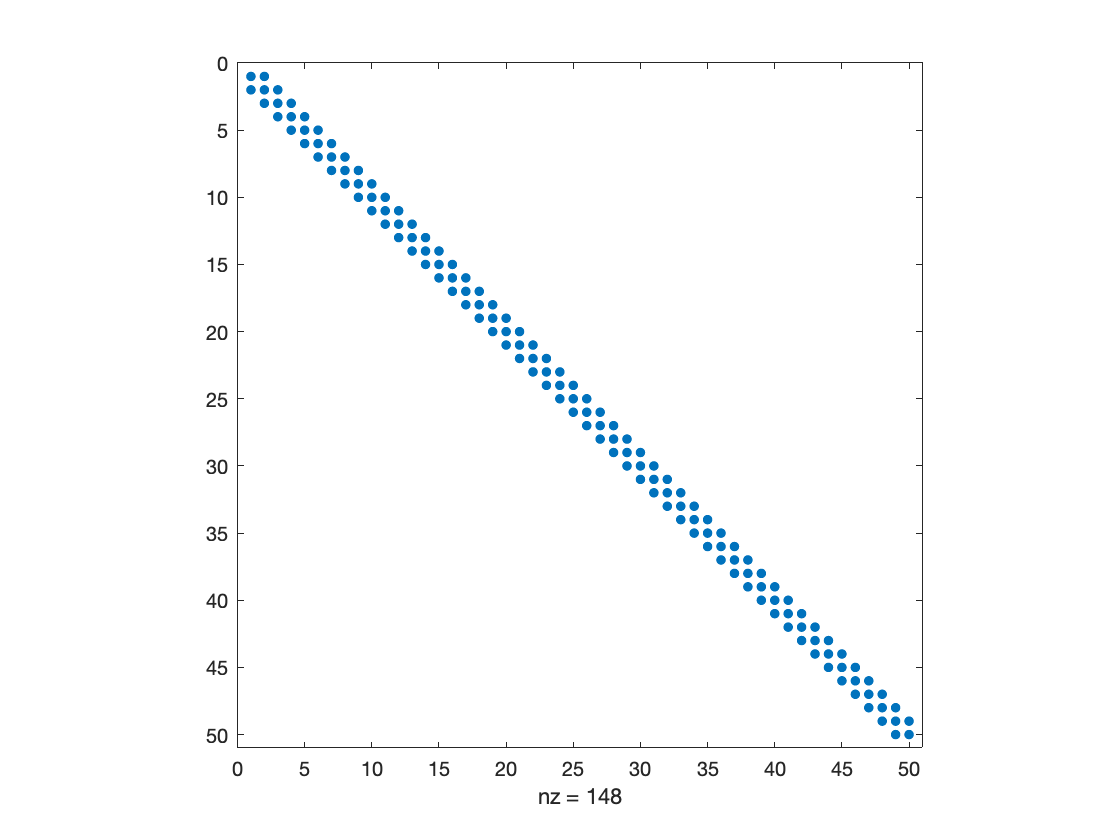

D = gallery('dorr',50);
spy(D)

c = condest(D)

c =      3.353970942411191e+06


e = ones(50,1);
b = D*e;
[sol, niter] = Jacobi(D,b,10^-6,30000)

sol =      5.689494803980587e-01
     3.469830582782696e-01
     2.303763712526022e-01
     1.678580040753758e-01
     1.336353733272751e-01
     1.145009919216790e-01
     1.035694781679772e-01
     9.718581267956170e-02
     9.337407307334124e-02
     9.104626916807979e-02


niter =        30000


B = (-1./diag(D)')'.*(D-diag(diag(D)));
raggio_spettrale = max(abs(eigs(B))) % Raggio spettrale

raggio_spettrale =      9.999969672077751e-01


err = norm(e-sol)/norm(sol)

err =      5.206942233857522e+00


In questo caso si testa una matrice ben condizionata la cui diagonale non è strettamente dominante.

n = 5000;
e = ones(n,1);
W = spdiags([e 5*e 2*e -e e], [-1300 -500 0 400 2500], n, n);
c = condest(W)

c =      4.620566761099261e+02


spy(W);

b = W*e;
[sol, niter] = Jacobi(W,b,10^(-5));

B = (-1./diag(W)')'.*(W-diag(diag(W)));
raggio_spettrale = max(abs(eigs(B))) % Raggio spettrale

raggio_spettrale =      3.320404824282580e+00


Il raggio spettrale è maggiore di 1, quindi il metodo iterativo non può convergere.

## Confronto temporale con bicg

Si riporta di seguito un confronto sui tempi di esecuzione tra la function `Jacobi` e quella del Matlab `bicg`. Nel primo esempio si utilizza una matrice sparsa di dimensione 5000x5000. Si può osservare come `bicg` sia più veloce di un ordine di grandezza, a parità di cifre significative richieste.

n = 5000;
e = ones(n,1);
A = spdiags([e 3*e 15*e -e e], [-1300 -500 0 400 2500], n, n);
b = A*e;
f = @()(bicg(A,b));
tempo_bicg = timeit(f)

bicg converged at iteration 10 to a solution with relative residual 7.3e-07.
bicg converged at iteration 10 to a solution with relative residual 7.3e-07.
bicg converged at iteration 10 to a solution with relative residual 7.3e-07.
bicg converged at iteration 10 to a solution with relative residual 7.3e-07.
bicg converged at iteration 10 to a solution with relative residual 7.3e-07.
bicg converged at iteration 10 to a solution with relative residual 7.3e-07.
bicg converged at iteration 10 to a solution with relative residual 7.3e-07.
bicg converged at iteration 10 to a solution with relative residual 7.3e-07.
bicg converged at iteration 10 to a solution with relative residual 7.3e-07.
bicg converged at iteration 10 to a solution with relative residual 7.3e-07.
bicg converged at iteration 10 to a solution with relative residual 7.3e-07.
bicg converged at iteration 10 to a solution with relative residual 7.3e-07.
bicg converged at iteration 10 to a solution with relative residual 7.3e-07.

tempo_bicg =      2.634263152500000e-03


g = @()(Jacobi(A,b));
tempo_Jacobi = timeit(g)

tempo_Jacobi =      5.683126615250000e-02


Nel secondo esempio si utilizza una matrice sparsa di dimensione 30000x30000.

n = 15000;
e = ones(15000,1);
A = spdiags([e 5*e 7*e -e e], [-3500 -400 0 7000 11000], n, n);
b = A*e;
f = @()(bicg(A,b,[],100));
tempo_bicg = timeit(f)

bicg converged at iteration 58 to a solution with relative residual 7.8e-07.
bicg converged at iteration 58 to a solution with relative residual 7.8e-07.
bicg converged at iteration 58 to a solution with relative residual 7.8e-07.
bicg converged at iteration 58 to a solution with relative residual 7.8e-07.
bicg converged at iteration 58 to a solution with relative residual 7.8e-07.
bicg converged at iteration 58 to a solution with relative residual 7.8e-07.
bicg converged at iteration 58 to a solution with relative residual 7.8e-07.
bicg converged at iteration 58 to a solution with relative residual 7.8e-07.
bicg converged at iteration 58 to a solution with relative residual 7.8e-07.
bicg converged at iteration 58 to a solution with relative residual 7.8e-07.
bicg converged at iteration 58 to a solution with relative residual 7.8e-07.
bicg converged at iteration 58 to a solution with relative residual 7.8e-07.
bicg converged at iteration 58 to a solution with relative residual 7.8e-07.

tempo_bicg =      2.739719315250000e-02


[sol niter] = Jacobi(A,b,10^-6,30000);
niter

niter =    119


g = @()(Jacobi(A,b,10^-6,30000));
tempo_Jacobi = timeit(g)

tempo_Jacobi =      3.342636901525000e-01


In questo caso si può notare come, oltre ad essere più veloce in termini di tempo d'esecuzione, `bicg` converge anche con la metà delle iterazioni.

## Confronto sui tempi di esecuzione tra la forma vettoriale e matriciale di Jacobi

In questo paragrafo, si confrontano i tempi di esecuzione della function `Jacobi` in cui una volta si calcolano le matrici B e C in modo vettoriale, un'altra in cui queste sono calcolate attraverso relazioni matriciali. Prima la modalità vettoriale:

n = 10000;
e = ones(n,1);
A = spdiags([e 3*e 15*e -e e], [-1300 -500 0 400 2500], n, n);
b = A*e;
g = @()(Jacobi(A,b));
Jacobi_vett = timeit(g)

Jacobi_vett =      2.329891259580000e-01


Qui il tempo d'esecuzione attraverso le relazioni matriciali, versione implementata nella function `Jacobi_matrici`:

n = 10000;
e = ones(n,1);
A = spdiags([e 3*e 15*e -e e], [-1300 -500 0 400 2500], n, n);
b = A*e;
g = @()(Jacobi_matrici(A,b));
Jacobi_matr = timeit(g)

Jacobi_matr =      3.009723990958000e+00


Si nota come il tempo d'esecuzione sia maggiore nel secondo caso, in quanto l'algoritmo prevede il calcolo di più prodotti tra matrici e soprattutto il calcolo di una matrice inversa.